## 1.用一次多项式拟合下列数据

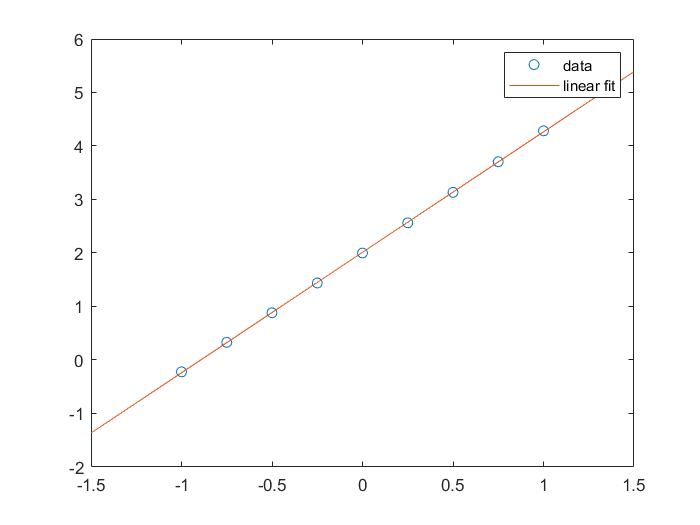

clear;clc;close all;
x=[-1.0 -0.75 -0.50 -0.25 0 0.25 0.50 0.75 1.00];
y=[-0.2209 0.3295 0.8826 1.4392 2.0003 2.5645 3.1334 3.7061 4.2836];
p=polyfit(x,y,1);
x1=linspace(-1.5,1.5);
y1=polyval(p,x1);
figure
plot(x,y,'o',x1,y1)
legend('data','linear fit')

## 2.用二次多项式拟合下列数据

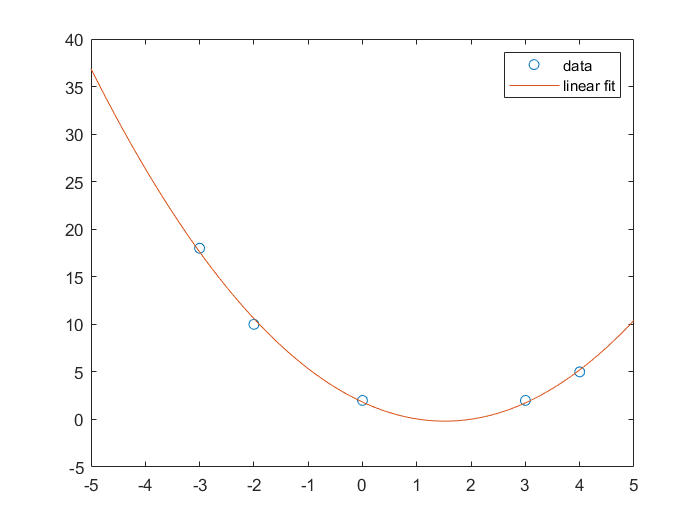

clear;clc;close all;
x=[-3 -2 0 3 4];
y=[18 10 2 2 5];
p=polyfit(x,y,2);
x1=linspace(-5,5);
y1=polyval(p,x1);
figure
plot(x,y,'o',x1,y1)
legend('data','linear fit')

## 3.令$x=-0.2:0.1:1,y=2x^5-3x^3-x^2-9$,利用产生的数据作多项式拟合和保形内插法拟合，比较两条拟合曲线。在原来的y值加上随机偏差0.1*rand(1,13),再作一次多项式拟合和保形拟合，看看结果有什么不同。

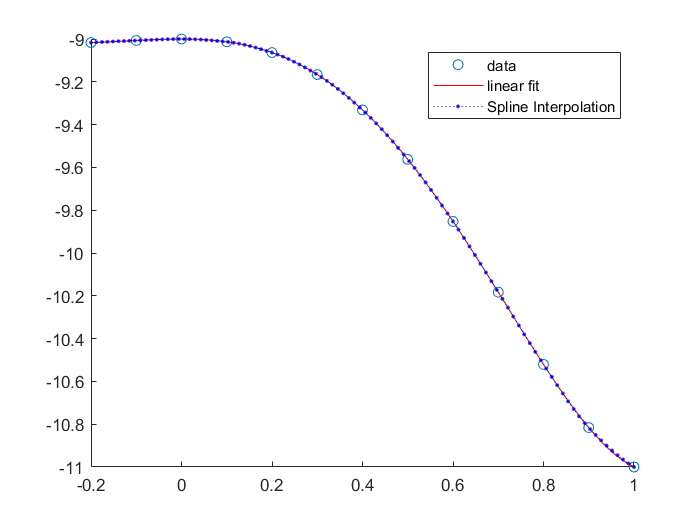

clear;clc;close all;
x=-0.2:0.1:1;
y=2*x.^5-3*x.^3-x.^2-9;
xq = linspace(-0.2,1);
figure
hold on;
plot(x,y,'o')
%多项式拟合
p=polyfit(x,y,5);
yp=polyval(p,xq);
plot(xq,yp,'r')
%插值拟合
yq = interp1(x,y,xq,'pchip');
plot(xq,yq,':.b')
legend('data','linear fit','Spline Interpolation')

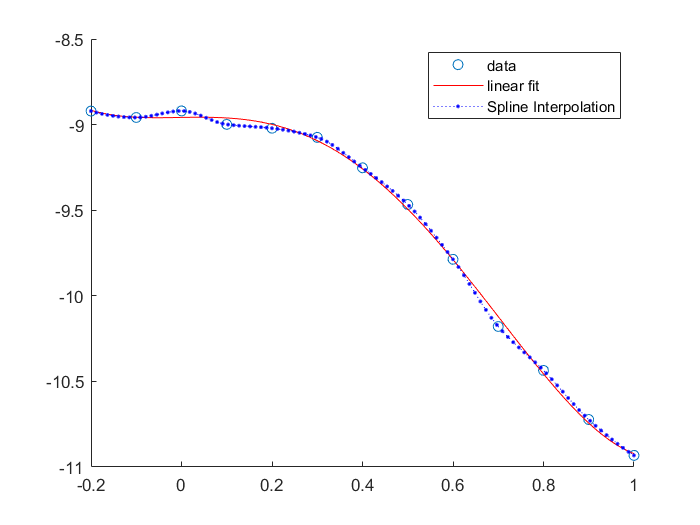

%加上随机偏差0.1*rand(1,13)
y=2*x.^5-3*x.^3-x.^2-9+0.1*rand(1,13);
figure
hold on;
plot(x,y,'o')
%多项式拟合
p=polyfit(x,y,5);
yp=polyval(p,xq);
plot(xq,yp,'r')
%插值拟合
yq = interp1(x,y,xq,'pchip');
plot(xq,yq,':.b')
legend('data','linear fit','Spline Interpolation')

## 4.用曲线拟合中8个不同的傅里叶级数、保形内插法对方形波数据进行拟合，比较结果。最后用快速傅里叶变换和反变换的指令对这组数据作运算。

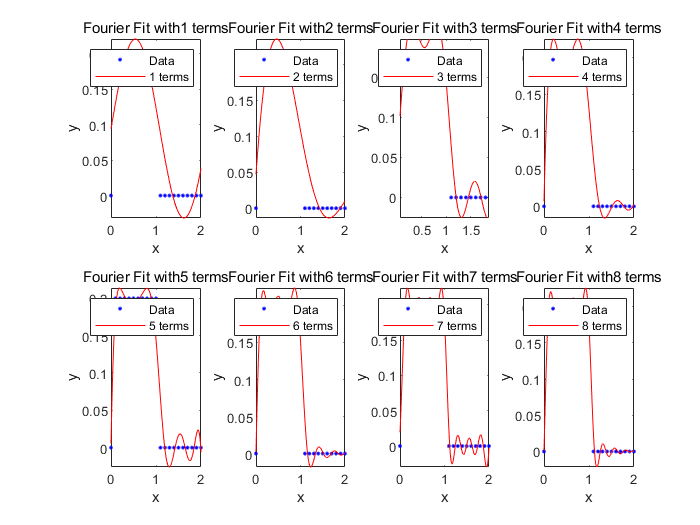

clear;clc;close all;
x=0:0.1:2;
y=[0 0.2 0.2 0.2 0.2 0.2 0.2 0.2 0.2 0.2 0.2 0 0 0 0 0 0 0 0 0 0];
%8个不同的傅里叶级数拟合
for m=1:8
    subplot(2,4,m)
    f=fit(x',y',['fourier',num2str(m)]);
    plot(f,x,y)
    legend('Data',[num2str(m),' terms'])
    title(['Fourier Fit with',num2str(m),' terms'])
end

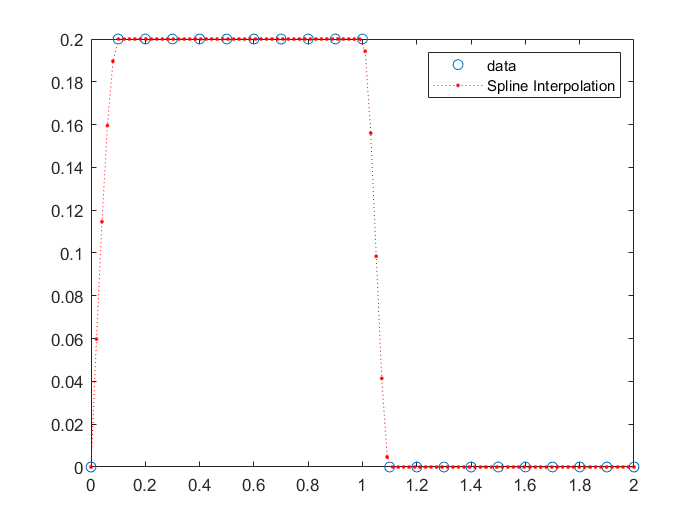

%保形内插法拟合
x=0:0.1:2;
y=[0 0.2 0.2 0.2 0.2 0.2 0.2 0.2 0.2 0.2 0.2 0 0 0 0 0 0 0 0 0 0];
figure
xq=linspace(0,2);
yq = interp1(x,y,xq,'pchip');
plot(x,y,'o',xq,yq,':.r')
legend('data','Spline Interpolation')

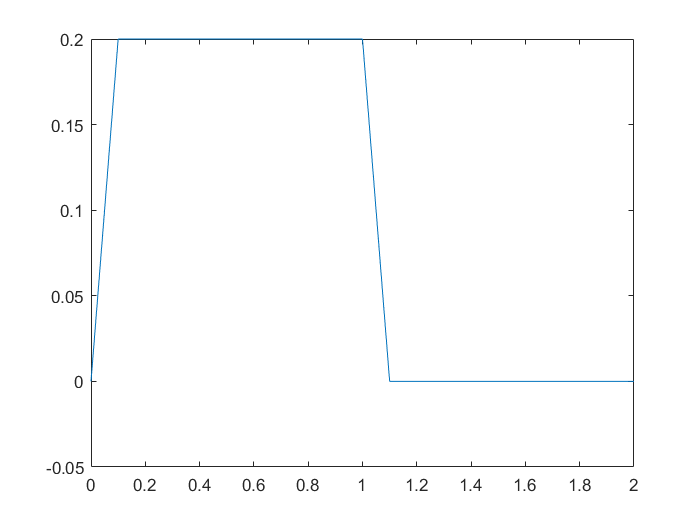

%fft and ifft
x=0:0.1:2;
y=[0 0.2 0.2 0.2 0.2 0.2 0.2 0.2 0.2 0.2 0.2 0 0 0 0 0 0 0 0 0 0];
f=fft(y);
ff=ifft(f);
plot(x,ff)

## 5.用指数公式拟合数据

clear;clc;close all;
x=[1 2 3 4 5 6 7 8];
y=[15.3 20.5 27.4 36.6 49.1 65.6 87.87 117.6];
%y=b*e^(ax)
lny=log(y);  %lny=a*x+lnb
p=polyfit(x,lny,1)

p =     0.2913    2.4367


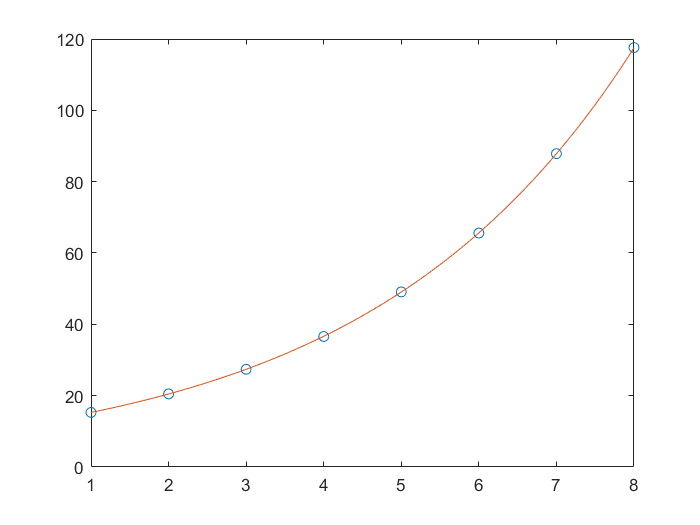

b=exp(p(2));
a=p(1);
xp=linspace(1,8);
yp=b*exp(1).^(a*xp);
plot(x,y,'o',xp,yp)

## 6.令$x=0:0.1:2,y=1/(7-x^2+x)$,再作有理函数拟合，比较与原函数差别，再作保形内插法拟合，比较结果。

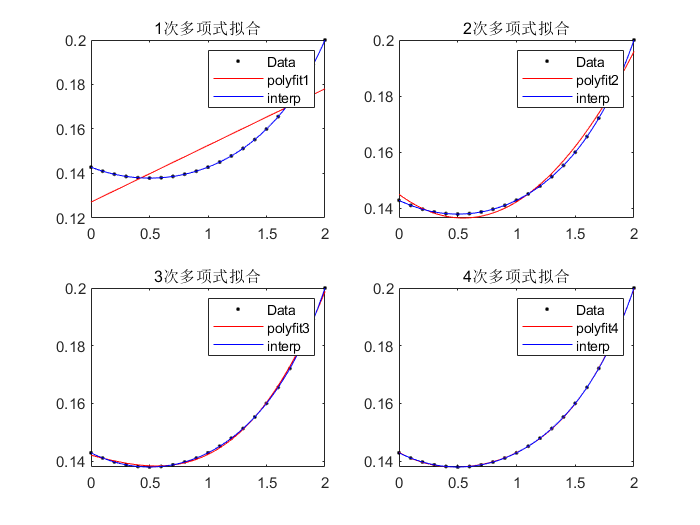

clear;clc;close all;
x=0:0.1:2;
y=1./(7-x.^2+x);
xq=linspace(0,2);
for n=1:4
    subplot(2,2,n)
    %有理函数拟合
    p=polyfit(x,y,n);
    y1=polyval(p,xq);
    %保形内插拟合
    y2=interp1(x,y,xq,"pchip");
    %画图
    plot(x,y,'.k',xq,y1,'r',xq,y2,'b')
    legend('Data',['polyfit',num2str(n)],'interp')
    title([num2str(n),'次多项式拟合'])
end

## 7.自己编写一个指数拟合的练习

#### 令$x=0.1:0.1:2,y=1.7*x^3$，再加上随机偏差2*rand(1,10)，利用生成的数据进行指数拟合。

clear;close all;clc;
x=0.1:0.1:2;
y=1.7*x.^(3)+2*rand(1,length(x));

y =     1.2943    1.4323    1.5553    0.6609    1.5719    1.6774    0.9083    1.1084    2.2360    3.6195    2.9435    4.1081    4.1825    6.1673    6.2477    7.9751    9.7503   11.6962   13.5789   14.6944


lny=log(y);  %lny=a*x+lnb
p=polyfit(x,lny,1)

p =     1.5114   -0.4172


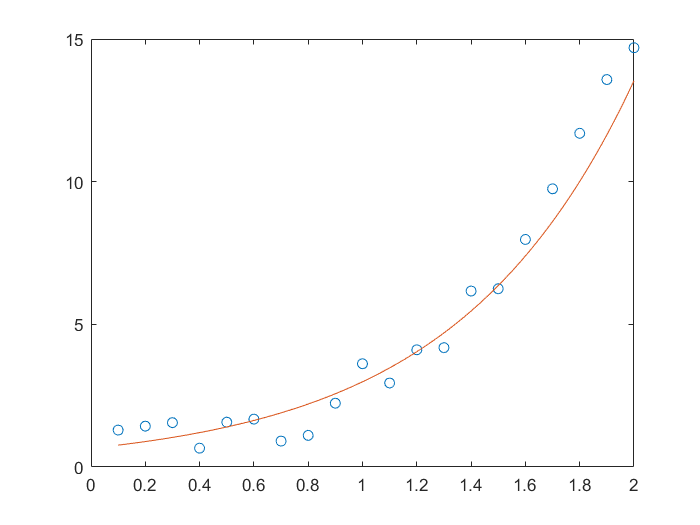

b=exp(p(2));
a=p(1);
xp=linspace(x(1),x(end));
yp=b*exp(1).^(a*xp);
plot(x,y,'o',xp,yp)

## 8.求方程$4cosx=e^x$的根，保留三位小数的有效数字

### （1）用对分法编程，取$x_0=\pi/4,x_1= \pi/2$;

clear;
f=@(x)exp(1)^x-4*cos(x); %在pi/4到pi/2上为单调增函数
x0=pi/4;
x1=pi/2;
Delta=0.001;
n=0;
if abs(f(x0))<Delta
    fprintf('方程的根为%.3f\n',f(x0))
elseif abs(f(x1))<Delta
    fprintf('方程的根为%.3f\n',f(x0))
elseif f(x0)*f(x1)>0
    fprintf('方程在此区间无根')
end
while f(x0)*f(x1)<0
    n=n+1;
    mid=(x0+x1)/2;
    if abs(f(mid))<Delta
        fprintf('方程的根为%.3f\n',mid);
        break
    elseif f(mid)*f(x0)>0
        x0=mid;
    else
        x1=mid;
    end
end

方程的根为0.905


fprintf('计算次数为%d\n',n);

计算次数为11


### （2）用牛顿法编程，取$x_0=\pi/4$;

clear;
f=@(x)exp(1)^x-4*cos(x);
df=@(x)exp(1)^x+4*sin(x);
x0=pi/4;
Delta=0.001;
n=0;
if abs(f(x0))<Delta
    fprintf('方程的根为%.3f\n',f(x0))
end
while abs(f(x0))>=Delta
    n=n+1;
    x1=x0-f(x0)/df(x0);
    if abs(f(x1))<=Delta
        fprintf('方程的根为%.3f',x1)
        break
    else
        x0=x1;
    end
end

方程的根为0.905

fprintf('计算次数为%d\n',n);

计算次数为2


### （3）用弦割法编程，取$x_0=\pi/4,x_1= \pi/2$;

clear;
f=@(x)exp(1)^x-4*cos(x);
x0=pi/4;
x1=pi/2;
Delta=0.001;
n=0;
x2=x1-f(x1)*(x1-x0)/(f(x1)-f(x0));
if abs(f(x0))<Delta
    fprintf('方程的根为%.3f\n',f(x0))
elseif abs(f(x1))<Delta
    fprintf('方程的根为%.3f\n',f(x1))
elseif abs(f(x2))<Delta
    fprintf('方程的根为%.3f\n',f(x2))
end
while abs(f(x2))>=Delta
    n=n+1;
    x0=x1;
    x1=x2;
    x2=x1-f(x1)*(x1-x0)/(f(x1)-f(x0));
    if abs(f(x2))<Delta
        fprintf('方程的根为%.3f\n',x2)
        break
    end
end

方程的根为0.905


fprintf('计算次数为%d\n',n);

计算次数为2


### （4）用指令fzero计算，取$x_0=\pi/4,x_1= \pi/2$;

f=@(x)exp(1)^x-4*cos(x);
x=fzero(f,[pi/4,pi/2]);
 fprintf('方程的根为%.3f\n',x);

方程的根为0.905


### 比较达到同样精度时前三种方法所需要的计算次数。

由程序运行输出结果可以看出：

对分法循环了13次；

牛顿法循环了2次；

弦割法循环了2次；

## 9.已知$y=x^4-4x^3-6x^2-16x+4$,在$-1<x<4$的区间内寻找方程的零点、极小值及对应的变量值。

clear;clc;close all;
y=@(x)x^4-4*x^3-6*x^2-16*x+4;
x0=fzero(y,[-1 4])

x0 = 0.2278

[minx,miny]=fminbnd(y,-1,4)

minx = 4.0000

miny = -156.0000

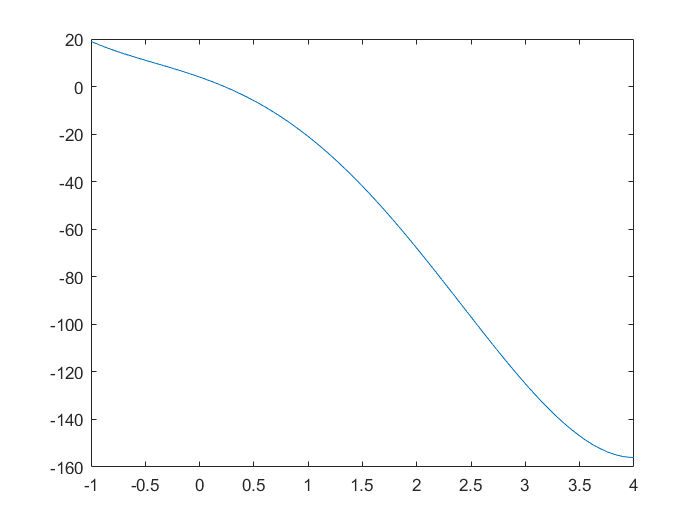

figure;
x=linspace(-1,4);
f=x.^4-4*x.^3-6*x.^2-16*x+4;
plot(x,f)

## 10.求函数$f(x,y)=x^2+25y^2-2x+50y+25$的极小点与极小值，寻找从初始点$x_0=2,y_0=3$开始。

clear;close all;clc;
f=@(x)x(1)^2+25*x(2)^2-2*x(1)+50*x(2)+25;
[xymin,fmin]=fminsearch(f,[2 3])

xymin =     1.0000   -1.0000


fmin = -1.0000

## 附加题 拟合下列数据：

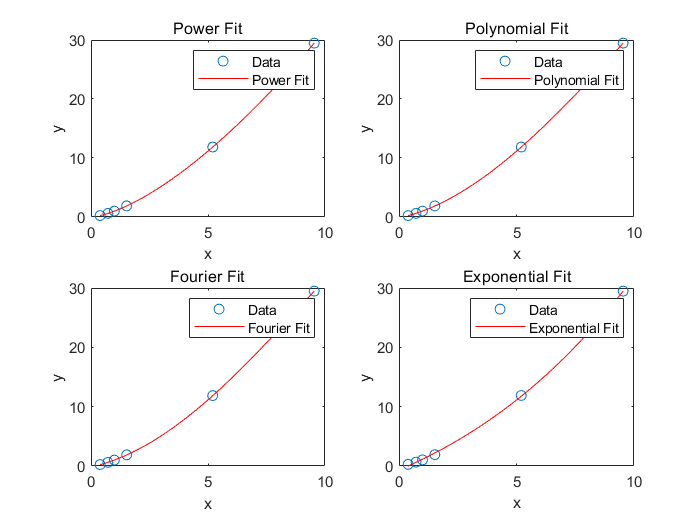

clear;close all;clc;
x=[0.3871 0.7233 1.0000 1.5237 5.2028 9.5388];
y=[0.2408 0.6152 1.0000 1.8808 11.862 29.475];
%幂函数拟合
subplot(2,2,1)
p=fit(x',y','Power1');
plot(p,x,y,'o')
legend('Data','Power Fit')
title('Power Fit')
%三次多项式拟合
subplot(2,2,2)
p=fit(x',y','poly3');
plot(p,x,y,'o')
legend('Data','Polynomial Fit')
title('Polynomial Fit')
%1项傅里叶级数拟合
subplot(2,2,3)
p=fit(x',y','fourier1');
plot(p,x,y,'o')
legend('Data','Fourier Fit')
title('Fourier Fit')
%指数拟合
subplot(2,2,4)
p=fit(x',y','exp2');
plot(p,x,y,'o')
legend('Data','Exponential Fit')
title('Exponential Fit')